# Figure of PCC K vs S

Get the data for a figure bar plot with results of regularized permutation DFA for males and females separately

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

% Get the vector ready for BatName, Sex and Deafness
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'BatID')
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
GGPath = dir('/Users/elie/Google Drive*');
try
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
catch ME
    Path2Paper = fullfile(GGPath.folder, GGPath.name, 'Mon Drive', 'BatmanData', 'Deaf Paper');
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'Mon Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
end

BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

PLim = 0.001;
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll4);
Mat_PCC_mean = nan(2*(length(UGroup)+1),2);
Mat_PCC_std = nan(2*(length(UGroup)+1),2);
NumSigMales = nan(length(UGroup)+1,2); % Column 1 number of permutation sets significanty different from observed data Column 2: total number of tests
NumSigFemales = nan(length(UGroup)+1,2);% Column 1 number of permutation sets significanty different from observed data Column 2: total number of tests
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std', 'PFisher_males');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std', 'PFisher_females');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_mean(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
    Mat_PCC_std(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,2);
    NumSigMales(GR,1) = sum(PFisher_males<PLim);
    NumSigFemales(GR,1) = sum(PFisher_females<PLim);
    NumSigMales(GR,2) = length(PFisher_males);
    NumSigFemales(GR,2) = length(PFisher_females);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std', 'PFisher_males')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std', 'PFisher_females')
GR=5;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_mean(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
Mat_PCC_std(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,2);
NumSigMales(GR,1) = sum(PFisher_males<PLim);
NumSigFemales(GR,1) = sum(PFisher_females<PLim);
NumSigMales(GR,2) = length(PFisher_males);
NumSigFemales(GR,2) = length(PFisher_females);

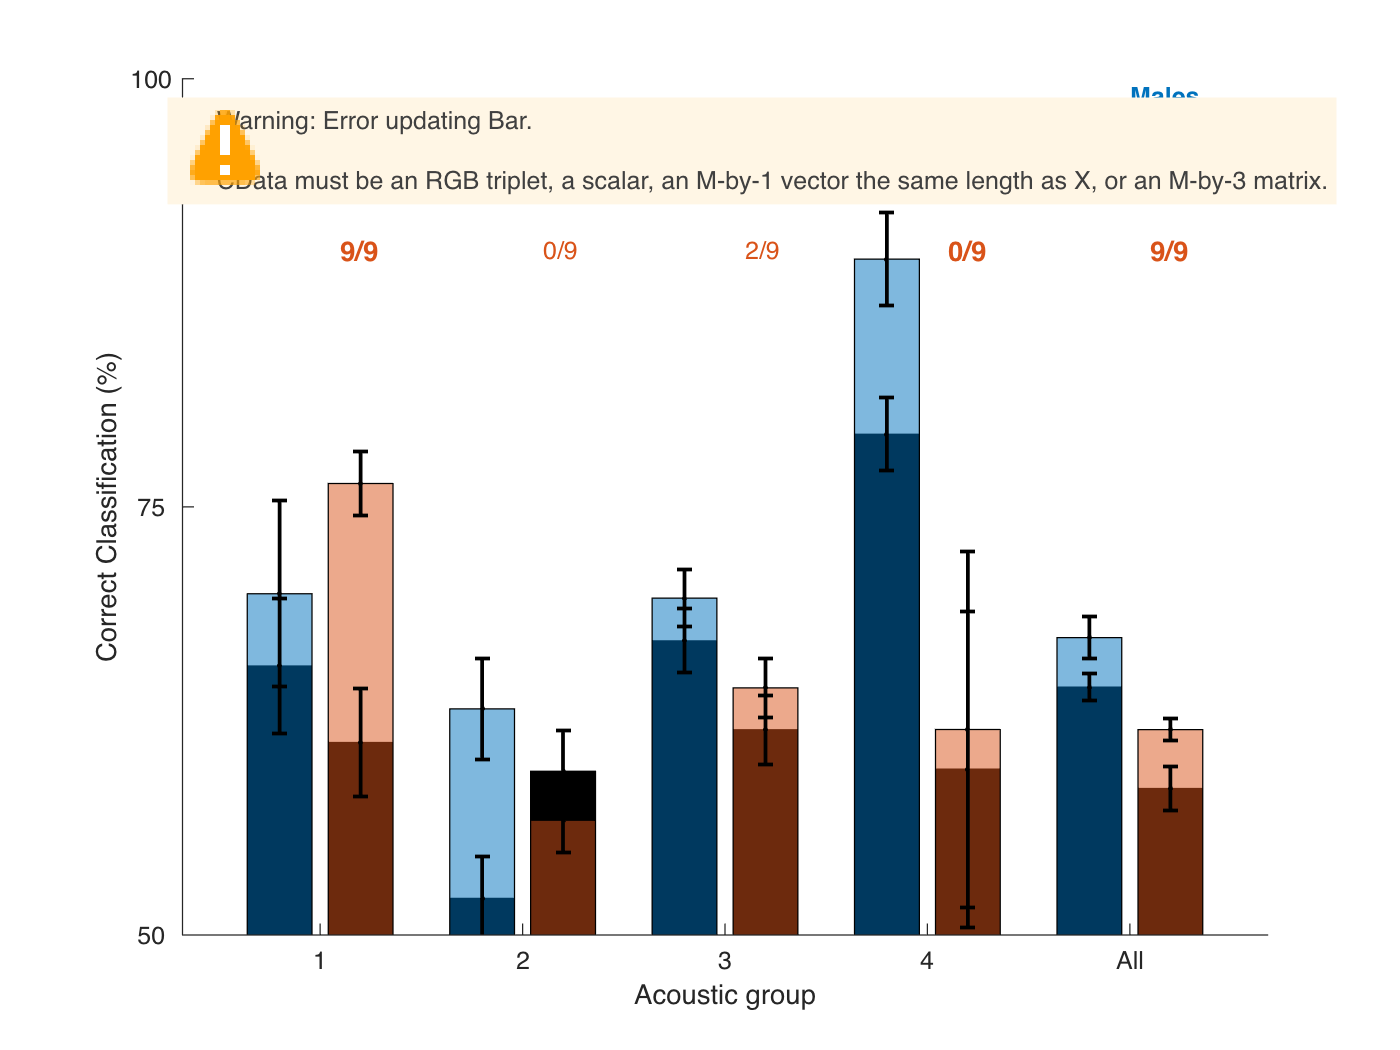


figure()
GR = length(UGroup);
X = reshape([1:GR+1; 1:GR+1] + repmat([-0.2;0.2], 1, GR+1), 1,(GR+1)*2);
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],5,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
set(gca,'XTick', 1:(GR+1))
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(5,99,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(5,97,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(5,95,'Chance','color','k', 'FontWeight', 'bold')
hold on
for GR=1:length(UGroup)+1
    if GR==2|| GR==4 || GR==5
        text(GR-0.3,94,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
    else
        text(GR-0.3,94,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:))
    end
    hold on
    if GR==1 || GR==4 || GR==5
        text(GR+0.1,90,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
    else
        text(GR+0.1,90,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:))
    end
end
hold off

Figure with all calls only

figure()
GR = length(UGroup);
X = [1 2];
bar(X,Mat_PCC_mean(9:10,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(9:10,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X,Mat_PCC_mean(9:10,2),Mat_PCC_std(9:10,2), Mat_PCC_std(9:10,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(9:10,1),Mat_PCC_std(9:10,1), Mat_PCC_std(9:10,1), 'k.','LineWidth',1.5)
ylim([50 75])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(2.5,74,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(2.5,72,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(2.5,70,'Chance','color','k', 'FontWeight', 'bold')
hold on
GR=5;
text(1,75, sprintf('n=%d', sum(contains(SexDeaf(MicAudioGood01), 'M'))))
hold on
text(1,74,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(2,71, sprintf('n=%d', sum(contains(SexDeaf(MicAudioGood01), 'F'))))
hold on
text(2,70,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off

Figure with G1 calls only

SexDeaf_mic = SexDeaf(MicAudioGood01);
Fig1 = figure();
GR = length(UGroup);
X = [1 2];
bar(X,Mat_PCC_mean(1:2,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(1:2,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X-0.05,Mat_PCC_mean(1:2,2),Mat_PCC_std(1:2,2), Mat_PCC_std(1:2,2), 'k.','LineWidth',1.5)
hold on
errorbar(X+0.05,Mat_PCC_mean(1:2,1),Mat_PCC_std(1:2,1), Mat_PCC_std(1:2,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(2.5,99,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(2.5,96,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(2.5,93,'Chance','color','k', 'FontWeight', 'bold')
hold on
GR=1;
text(1,80, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==1), 'M'))))
hold on
text(1,77,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(2,83, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==1), 'F'))))
hold on
text(2,80,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off
Fig1.Units = 'inches';
Fig1.Position(3:4) = [3 3];
Fig1.PaperSize = [3 3];
print(Fig1,fullfile(Path2Paper,'PCC_TmicAll4_perSex_G1.pdf'),'-dpdf','-fillpage')

Figure with G4 calls only

SexDeaf_mic = SexDeaf(MicAudioGood01);
Fig2=figure();
GR = length(UGroup);
X = [1 2];
bar(X,Mat_PCC_mean(7:8,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(7:8,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X-0.05,Mat_PCC_mean(7:8,2),Mat_PCC_std(7:8,2), Mat_PCC_std(7:8,2), 'k.','LineWidth',1.5)
hold on
errorbar(X+0.05,Mat_PCC_mean(7:8,1),Mat_PCC_std(7:8,1), Mat_PCC_std(7:8,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(2.5,99,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(2.5,96,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(2.5,93,'Chance','color','k', 'FontWeight', 'bold')
hold on
GR=4;
text(1,99, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==GR), 'M'))))
hold on
text(1,96,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(2,83, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==GR), 'F'))))
hold on
text(2,80,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off
Fig2.Units = 'inches';
Fig2.Position(3:4) = [3 3];
Fig2.PaperSize = [3 3];
print(Fig2,fullfile(Path2Paper,'PCC_TmicAll4_perSex_G4.pdf'),'-dpdf','-fillpage')

Figure with male only data for GRC poster

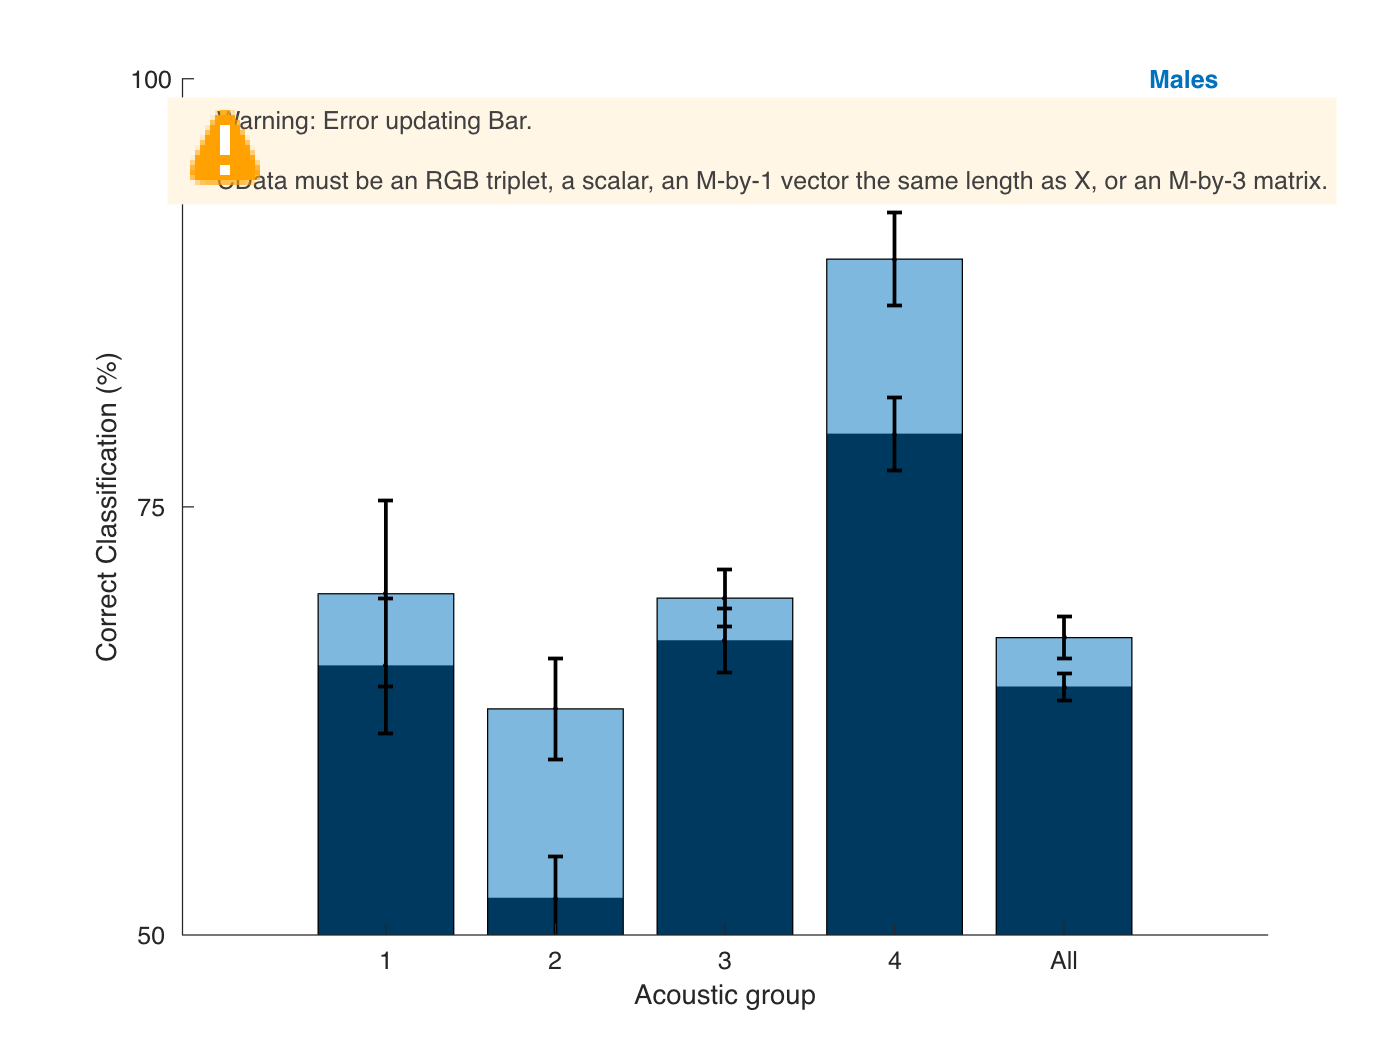

figure()
MaleVal = 1:2:10; %1:2:14;
GR = length(UGroup);
X = 1:GR+1;
bar(X,Mat_PCC_mean(MaleVal,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(MaleVal,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat(ColorCode(1,:),5,1);
hold on
errorbar(X,Mat_PCC_mean(MaleVal,2),Mat_PCC_std(MaleVal,2), Mat_PCC_std(MaleVal,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(MaleVal,1),Mat_PCC_std(MaleVal,1), Mat_PCC_std(MaleVal,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(5.5,100,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(5.5,96,'Chance','color','k', 'FontWeight', 'bold')
hold on
for GR=1:length(UGroup)+1
    if GR==2|| GR==4 || GR==5
        text(GR-0.2,94,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
    else
        text(GR-0.2,94,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:))
    end
end
hold off

Figure with female only data for poster

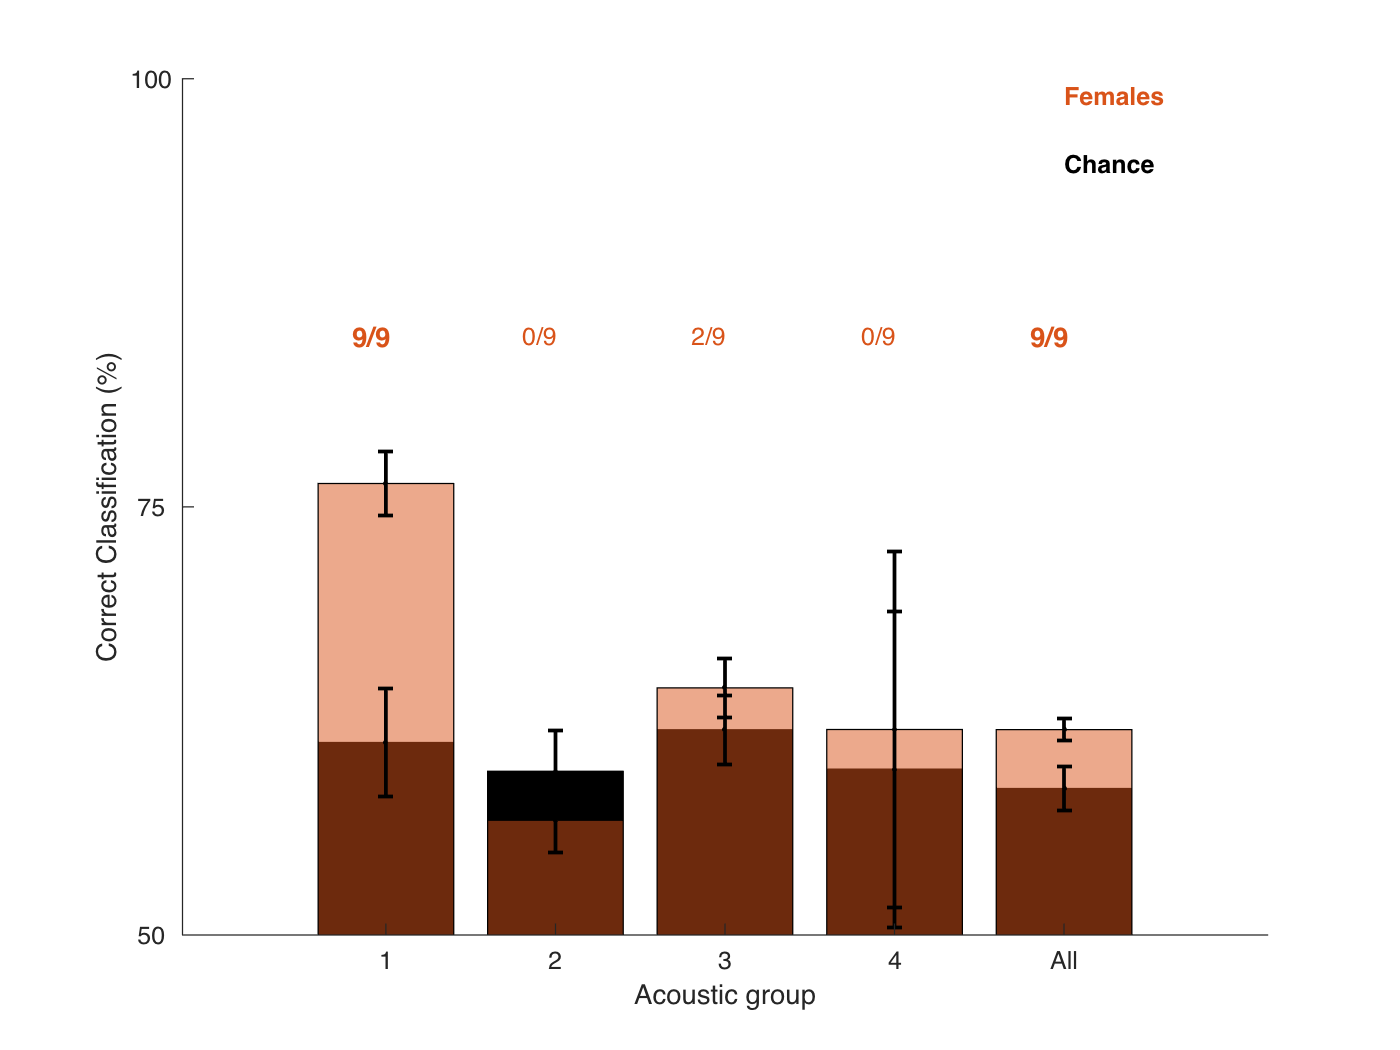

figure()
FemaleVal = 2:2:10;
GR = length(UGroup);
X = 1:GR+1;
bar(X,Mat_PCC_mean(FemaleVal,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(FemaleVal,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat(ColorCode(2,:),5,1);
hold on
errorbar(X,Mat_PCC_mean(FemaleVal,2),Mat_PCC_std(FemaleVal,2), Mat_PCC_std(FemaleVal,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(FemaleVal,1),Mat_PCC_std(FemaleVal,1), Mat_PCC_std(FemaleVal,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(5,99,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(5,95,'Chance','color','k', 'FontWeight', 'bold')
hold on
for GR=1:length(UGroup)+1
    if GR==1 || GR==5
        text(GR-0.2,85,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
    else
        text(GR-0.2,85,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:))
    end
end
hold off

Big figure panel with all results of RPDFA per Sex for all and Acsoutic group 1 and 4

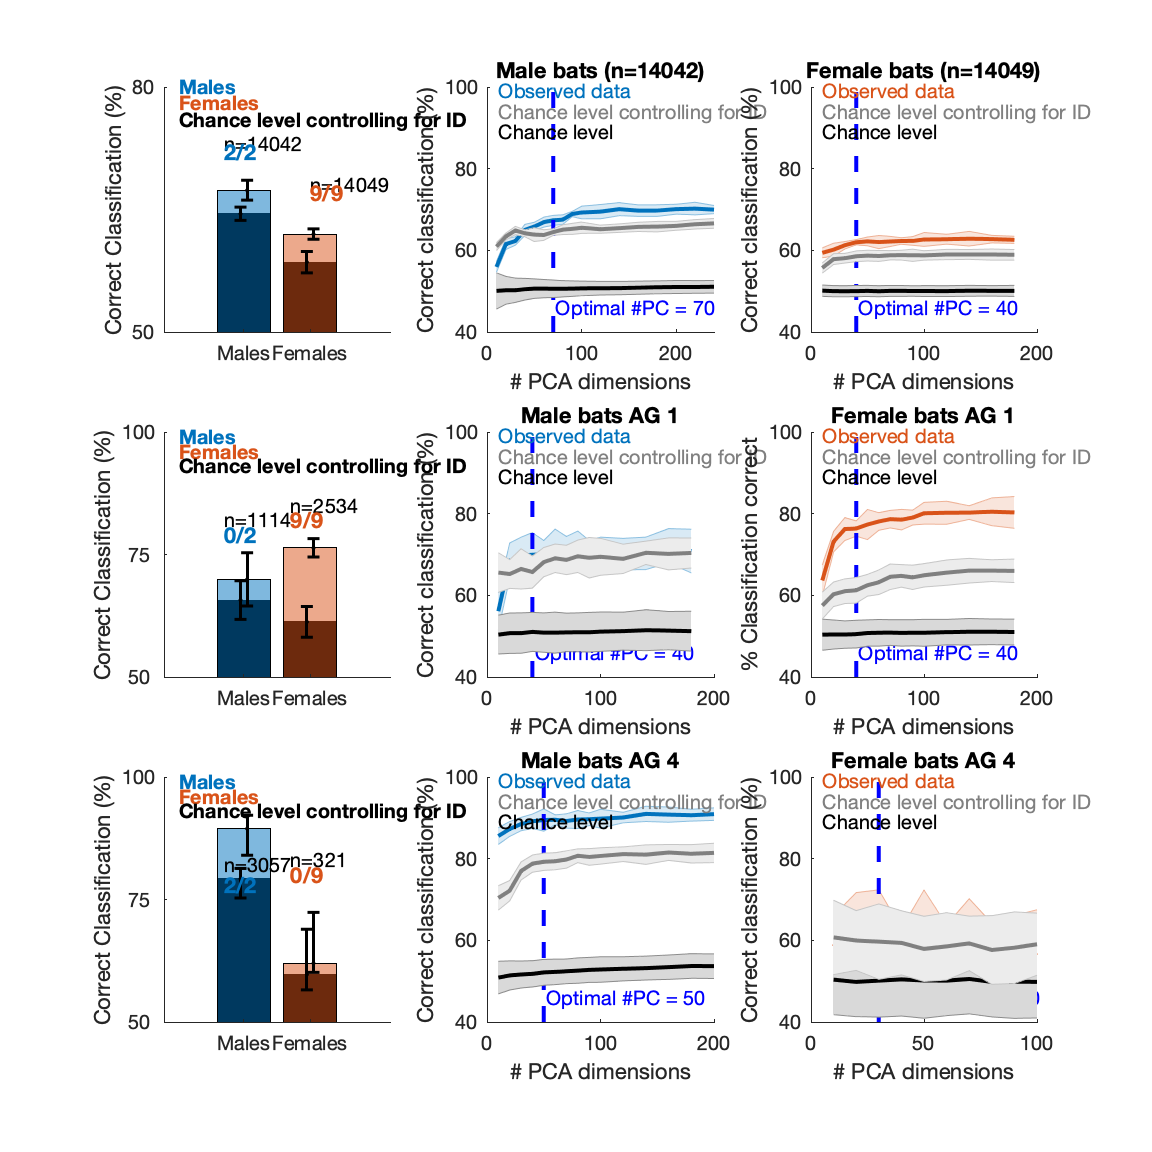

FIG = figure(1);
clf
set(gcf,'Visible','on')
PLim = 0.001;
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
SexDeaf_mic = SexDeaf(MicAudioGood01);

% First ow, results for all calls per sex
subplot(3,3,1)
GR = length(UGroup);
X = [1 2];
bar(X,Mat_PCC_mean(9:10,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(9:10,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X-0.05,Mat_PCC_mean(9:10,2),Mat_PCC_std(9:10,2), Mat_PCC_std(9:10,2), 'k.','LineWidth',1.5)
hold on
errorbar(X+0.05,Mat_PCC_mean(9:10,1),Mat_PCC_std(9:10,1), Mat_PCC_std(9:10,1), 'k.','LineWidth',1.5)
ylim([50 80])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 80], 'YTickLabel', [50 80]);
text(0.02,80,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(0.02,78,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(0.02,76,'Chance level controlling for ID','color','k', 'FontWeight', 'bold')
hold on
GR=5;
text(0.7,73, sprintf('n=%d', sum(contains(SexDeaf(MicAudioGood01), 'M'))))
hold on
text(0.7,72,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(2,68, sprintf('n=%d', sum(contains(SexDeaf(MicAudioGood01), 'F'))))
hold on
text(2,67,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off

subplot(3,3,2);
load(fullfile(LocalDataDir,'DeafBats_RegularizedPermDFA_MaleCalls.mat'),  'PC_val_M', 'NPC_opt_M','L_males', 'PFisher_males', 'PCC_males_mean_std', 'Lperm_males', 'PCCperm_males_mean_std', 'Lrand_males', 'PCCrand_males_mean_std', 'PC_DF_males')
PC_val_plot = PC_val_M(1:size(PCCrand_males_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_males_mean_std(1:length(PC_val_plot),1),PCC_males_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(1,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('Correct classification (%)')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_M, 'b--', sprintf('Optimal #PC = %d', NPC_opt_M));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_males_mean_std(:,1),PCCrand_males_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_males_mean_std(:,1),PCCperm_males_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(1,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Male bats (n=%d)',  sum(contains(SexDeaf_mic, 'M'))))
box off

subplot(3,3,3)
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleCalls.mat'),  'PC_val_F', 'NPC_opt_F','L_females', 'PFisher_females', 'PCC_females_mean_std', 'Lperm_females', 'PCCperm_females_mean_std', 'Lrand_females', 'PCCrand_females_mean_std', 'PC_DF_females')
PC_val_plot = PC_val_F(1:size(PCCrand_females_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_females_mean_std(1:length(PC_val_plot),1),PCC_females_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(2,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('Correct classification (%)')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_F, 'b--', sprintf('Optimal #PC = %d', NPC_opt_F));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_females_mean_std(:,1),PCCrand_females_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_females_mean_std(:,1),PCCperm_females_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(2,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Female bats (n=%d)',sum(contains(SexDeaf_mic, 'F'))))
box off

% second Row for Acsoutic group 1
SexDeaf_mic = SexDeaf(MicAudioGood01);
X = [1 2];
subplot(3,3,4)
bar(X,Mat_PCC_mean(1:2,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(1:2,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X-0.05,Mat_PCC_mean(1:2,2),Mat_PCC_std(1:2,2), Mat_PCC_std(1:2,2), 'k.','LineWidth',1.5)
hold on
errorbar(X+0.05,Mat_PCC_mean(1:2,1),Mat_PCC_std(1:2,1), Mat_PCC_std(1:2,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(0.02,99,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(0.02,96,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(0.02,93,'Chance level controlling for ID','color','k', 'FontWeight', 'bold')
hold on
GR=1;
text(0.7,82, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==1), 'M'))))
hold on
text(0.7,79,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(1.7,85, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==1), 'F'))))
hold on
text(1.7,82,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off

subplot(3,3,5)
GR=1;
load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','L_males', 'PFisher_males', 'PCC_males_mean_std', 'Lperm_males', 'PCCperm_males_mean_std', 'Lrand_males', 'PCCrand_males_mean_std', 'PC_DF_males')
PC_val_plot = PC_val_M(1:size(PCCrand_males_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_males_mean_std(1:length(PC_val_plot),1),PCC_males_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(1,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('Correct classification (%)')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_M, 'b--', sprintf('Optimal #PC = %d', NPC_opt_M));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_males_mean_std(:,1),PCCrand_males_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_males_mean_std(:,1),PCCperm_males_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(1,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Male bats AG %d', GR))
box off

subplot(3,3,6)
load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','L_females', 'PFisher_females', 'PCC_females_mean_std', 'Lperm_females', 'PCCperm_females_mean_std', 'Lrand_females', 'PCCrand_females_mean_std', 'PC_DF_females')
PC_val_plot = PC_val_F(1:size(PCCrand_females_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_females_mean_std(1:length(PC_val_plot),1),PCC_females_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(2,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('% Classification correct')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_F, 'b--', sprintf('Optimal #PC = %d', NPC_opt_F));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_females_mean_std(:,1),PCCrand_females_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_females_mean_std(:,1),PCCperm_females_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(2,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Female bats AG %d', GR))
box off

% third row for Acsoutic group 4
SexDeaf_mic = SexDeaf(MicAudioGood01);
X = [1 2];
subplot(3,3,7)
bar(X,Mat_PCC_mean(7:8,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(7:8,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],1,1);
hold on
errorbar(X-0.05,Mat_PCC_mean(7:8,2),Mat_PCC_std(1:2,2), Mat_PCC_std(7:8,2), 'k.','LineWidth',1.5)
hold on
errorbar(X+0.05,Mat_PCC_mean(7:8,1),Mat_PCC_std(1:2,1), Mat_PCC_std(7:8,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
set(gca,'XTick', 1:2)
XTL = get(gca,'XTickLabel');
XTL = {'Males' 'Females'};
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(0.02,99,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(0.02,96,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(0.02,93,'Chance level controlling for ID','color','k', 'FontWeight', 'bold')
hold on
GR=4;
text(0.7,82, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==4), 'M'))))
hold on
text(0.7,78,sprintf('%d/%d',NumSigMales(GR,1), NumSigMales(GR,2)), 'Color', ColorCode(1,:), 'FontWeight','bold', 'FontSize',11)
hold on
text(1.7,83, sprintf('n=%d', sum(contains(SexDeaf_mic(TmicAll4==4), 'F'))))
hold on
text(1.7,80,sprintf('%d/%d',NumSigFemales(GR,1), NumSigFemales(GR,2)), 'Color', ColorCode(2,:), 'FontWeight','bold', 'FontSize',11);
hold off

subplot(3,3,8)
GR=4;
load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','L_males', 'PFisher_males', 'PCC_males_mean_std', 'Lperm_males', 'PCCperm_males_mean_std', 'Lrand_males', 'PCCrand_males_mean_std', 'PC_DF_males')
PC_val_plot = PC_val_M(1:size(PCCrand_males_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_males_mean_std(1:length(PC_val_plot),1),PCC_males_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(1,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('Correct classification (%)')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_M, 'b--', sprintf('Optimal #PC = %d', NPC_opt_M));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_males_mean_std(:,1),PCCrand_males_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_males_mean_std(:,1),PCCperm_males_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(1,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Male bats AG %d', GR))
box off

subplot(3,3,9)
load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','L_females', 'PFisher_females', 'PCC_females_mean_std', 'Lperm_females', 'PCCperm_females_mean_std', 'Lrand_females', 'PCCrand_females_mean_std', 'PC_DF_females')
PC_val_plot = PC_val_F(1:size(PCCrand_females_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_females_mean_std(1:length(PC_val_plot),1),PCC_females_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(2,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('Correct classification (%)')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_F, 'b--', sprintf('Optimal #PC = %d', NPC_opt_F));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_females_mean_std(:,1),PCCrand_females_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_females_mean_std(:,1),PCCperm_females_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/20,99, 'Observed data', 'Color', ColorCode(2,:))
text(XLim(2)/20,89, 'Chance level', 'Color', 'k')
text(XLim(2)/20,94, 'Chance level controlling for ID', 'Color', [0.5 0.5 0.5])
title(sprintf('Female bats AG %d', GR))
box off


FIG.PaperOrientation = 'landscape';
FIG.Units = 'inches';
FIG.Position(3:4) = [8 8];
FIG.PaperSize = [8 8];
print(FIG,fullfile(Path2Paper,'SupFigure7_PCADFA_sex_allG1G4_TmicAll4.pdf'),'-dpdf','-fillpage')

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll4);
Mat_PCC_mean = nan((length(UGroup)+1),2);
Mat_PCC_std = nan((length(UGroup)+1),2);
NumSig = nan(length(UGroup)+1,2); % Column 1 number of permutation sets significanty different from observed data Column 2: total number of tests
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_AcGroup%d.mat', GR)),  'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std','PFisher');
    NPC_opt_ind = find(PC_val==NPC_opt_all);
    Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
    Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);
    NumSig(GR,1) = sum(PFisher<PLim);
    NumSig(GR,2) = length(PFisher);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_AllCalls.mat'), 'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std', 'PFisher')
GR=5;
NPC_opt_ind = find(PC_val==NPC_opt_all);
Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);
NumSig(GR,1) = sum(PFisher<PLim);
NumSig(GR,2) = length(PFisher);

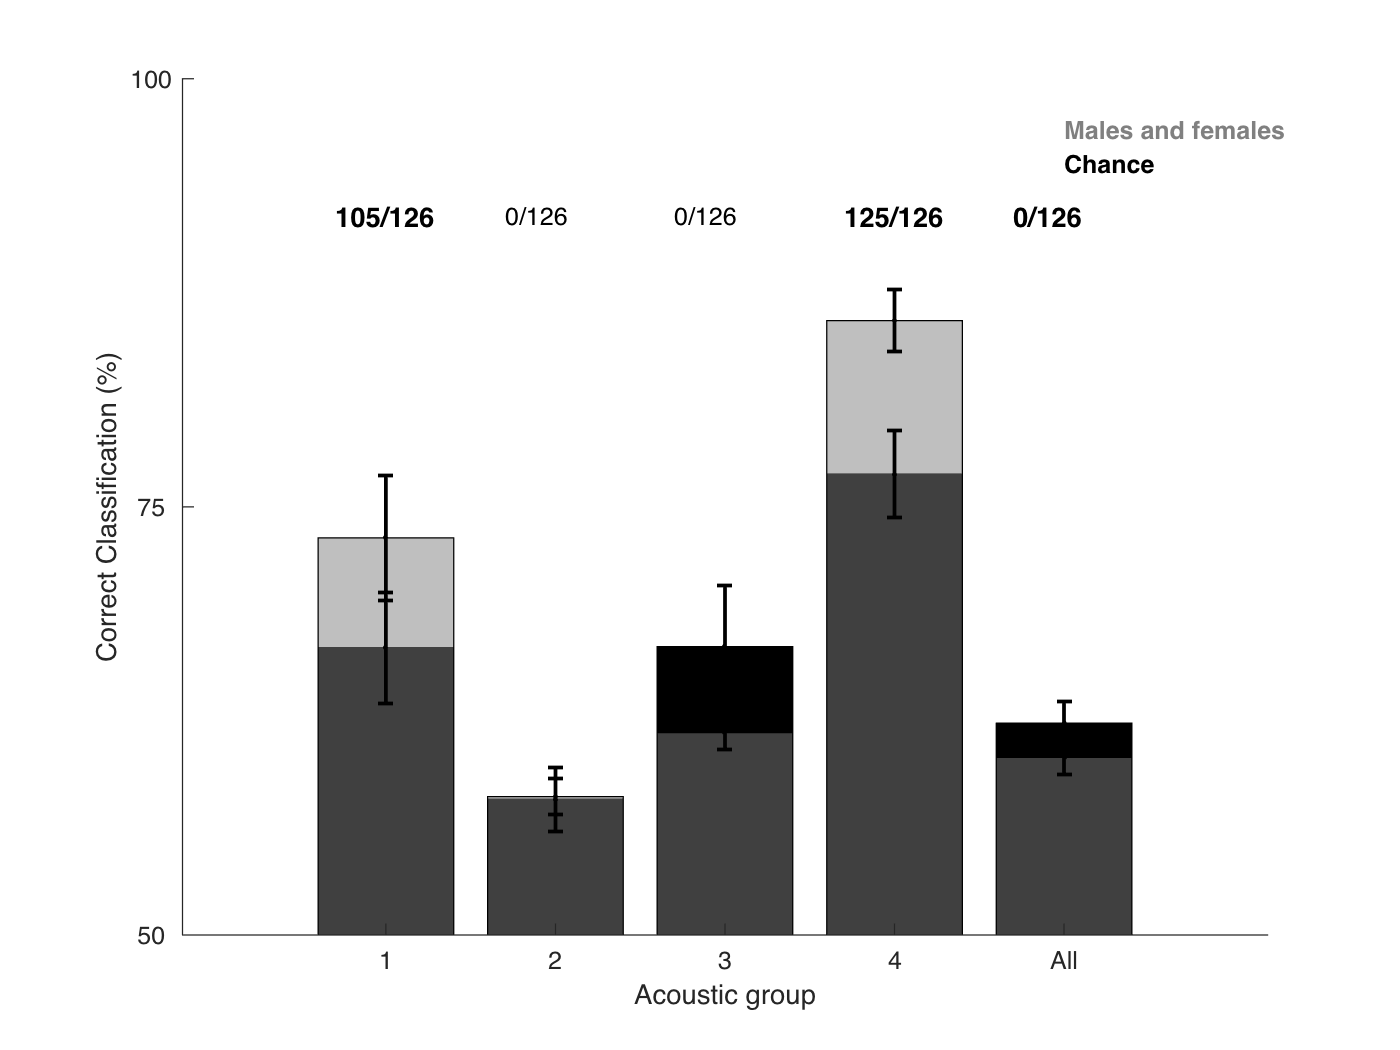


figure()
GR = length(UGroup);
X = 1:GR+1;
B1=bar(X,Mat_PCC_mean(:,2),'FaceColor', [0 0 0]);
hold on
B2=bar(X,Mat_PCC_mean(:,1));
B2.CData = repmat([0.5 0.5 0.5],5,1);
B2.FaceColor = 'flat'; B2.FaceAlpha = 0.5;
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
hold on
text(5,97,'Males and females','color',[0.5 0.5 0.5], 'FontWeight', 'bold')
hold on
text(5,95,'Chance','color','k', 'FontWeight', 'bold')
hold on
for GR=1:length(UGroup)+1
    if GR==1 || GR==4 || GR==5
        text(GR-0.3,92,sprintf('%d/%d',NumSig(GR,1), NumSig(GR,2)), 'FontWeight','bold', 'FontSize',11)
    else
        text(GR-0.3,92,sprintf('%d/%d',NumSig(GR,1), NumSig(GR,2)))
    end
    hold on
end
hold off